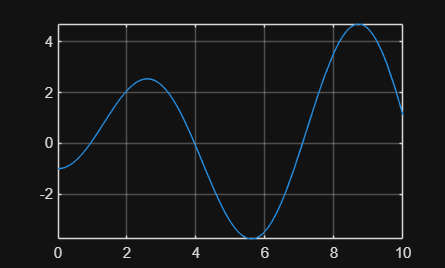

format long

f = @(x) 2 .* x .* besselj(1, x) - besselj(0, x);
fd = @(x) 2 .* x .* besselj(0, x) + besselj(1, x);


fplot(f,[0,10])

grid on


[z1,ni1]=Newton(f,fd,1.4,0,1e-10,50);
[z2,ni2]=Newton(f,fd,3,0,1e-10,50);
[z3,ni3]=Newton(f,fd,6.5,0,1e-10,50);


f([z1,z2,z3])

ans = 1.0e-14 *

   0.011102230246252  -0.272004641033163   0.061062266354384



[zs1,ns1]=secand(f,0.2,1.4,0,1e-10,50);

Error using Ultimul>secand
Too many input arguments.

[zs2,ns2]=secand(f,0.2,1.4,0,1e-10,50);
[zs3,ns3]=secand(f,0.2,1.4,0,1e-10,50);

[zs1, val1, iter1] = secant(f, 0.5, 1.5);
[zs2, val2, iter2] = secant(f, 3.5, 4.5);
[zs3, val3, iter3] = secant(f, 7.0, 8.0);

function [z,ni]=Newton(f,fd,x0,ea,er,nmax)
%-f functia
%fd derivata
%x0 aproixmata initiala



if nargin < 4, ea = 1e-3; end
    if nargin < 5, er = 0; end
    if nargin < 6, nmax = 50; end

xp=x0(:);

for k=1:nmax

    xc=xp-fd(xp)\f(xp);
    if norm (xc-xp,inf)<ea+er*norm(xc,inf);
        z=xc;
        ni=k;
        return
    end
    xp=xc;
end
error('S-a depasit numarul maxim de iteratii')
end

function [x2,val_f,i]=secand(f,x0,x1)
err=1e-10;
NrMaxIt=50;
for i=1:NrMaxIt
    x2=(x0*f(x1)-x1*f(x0))/(f(x1)-f(x0));
    if abs(f(x2))<err||abs(x2-x1)<err||abs(x2-x1)/abs(x2)<err
        val_f=f(x2);
        return;
    end
    x0=x1;
    x1=x2;
end
end

Problema 2 

f=@(x)[x(1)*exp(x(2))+x(3)-10;...
    x(1)*exp(2*x(2))+2*x(3) -12; ...
    x(1)*exp(3*x(2))+3*x(2)-18];